# Wavefront, MTF and PSF

The wavefront aberration structure specifies the PSF and MTF.  We illustrate how to calculate these quantities,

- For the diffraction limited case,

- With various levels of defocus

ieInit

## Create the diffraction-limited wavefront object

The wavefront struct, along wvfGet/Set/Plot, manage the wavefront calculations.

wvf0 = wvfCreate;   % Create a default struct

The wavefront data were measured with some parameters.  We do our calculations with parameters within the bounds of the measurements.

wave = 550;
wvf0 = wvfSet(wvf0, 'measured wavelength', wave);
wvf0 = wvfSet(wvf0, 'calc wavelengths', wave);

Calculate the PSF (and OTF) for the default wavefront parameters. The key parameters are wavelength and Zernike polynomial coefficients.

wvf0 = wvfCompute(wvf0);

## Vary defocus and plot a slice through the PSF

Set the defocus in diopters by adjusting the Zernike polynomial term for 'defocus'.  We recompute the PSF and plot a slice through the PSF function.

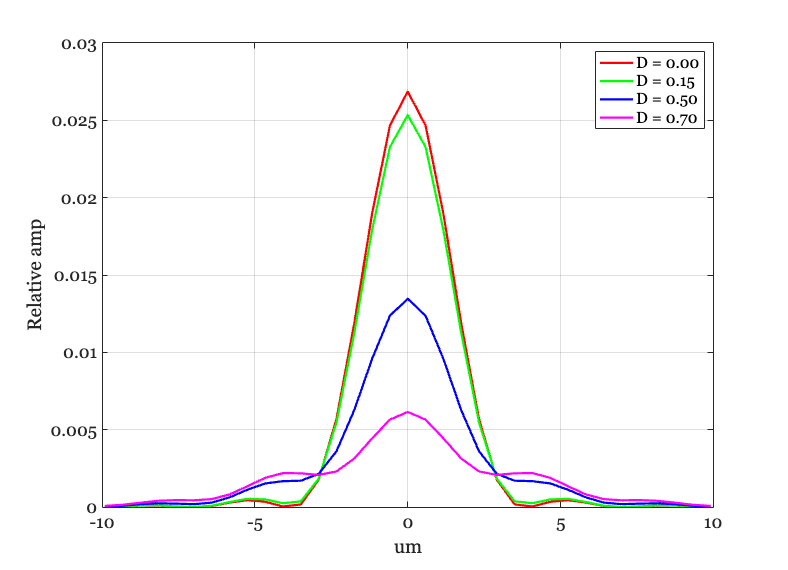

ieNewGraphWin;
d = [0 , 0.15, 0.5, 0.7];  % Defocus in diopters
thisL = cell(length(d),1);

for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});  % Change the defocus coefficient
    wvf1 = wvfCompute(wvf1);

    wvfPlot(wvf1, '1d psf', 'unit','um', 'plot range', 10, 'window', false);
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
end

hold off
xlabel('um'); ylabel('Relative amp'); grid on
legend(thisL);

## Compare the two pointspread functions (PSF)

We compare defocus of 0 and 0.5 diopters.  We would like to have some method of confirming that the defocus of 0.5 diopters produces this amount of spread.

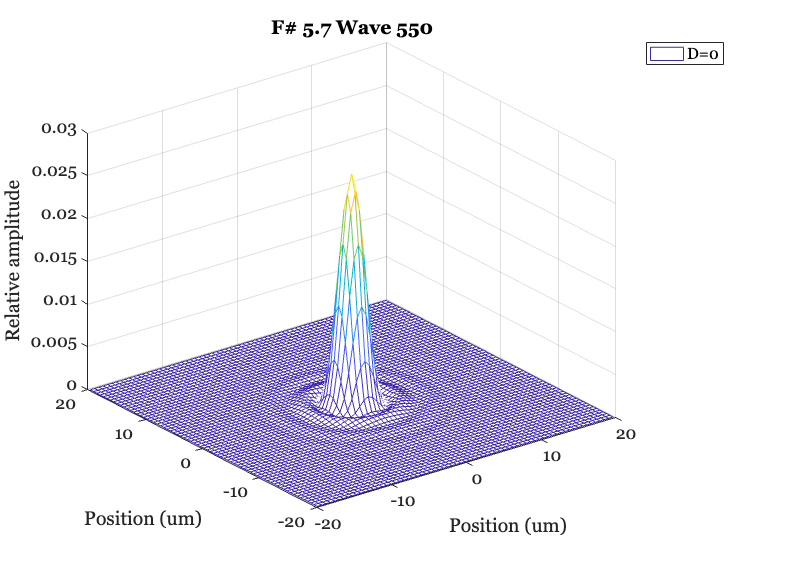

wvfPlot(wvf0, 'psf', 'unit','um', 'plot range', 20);
legend({'D=0'})

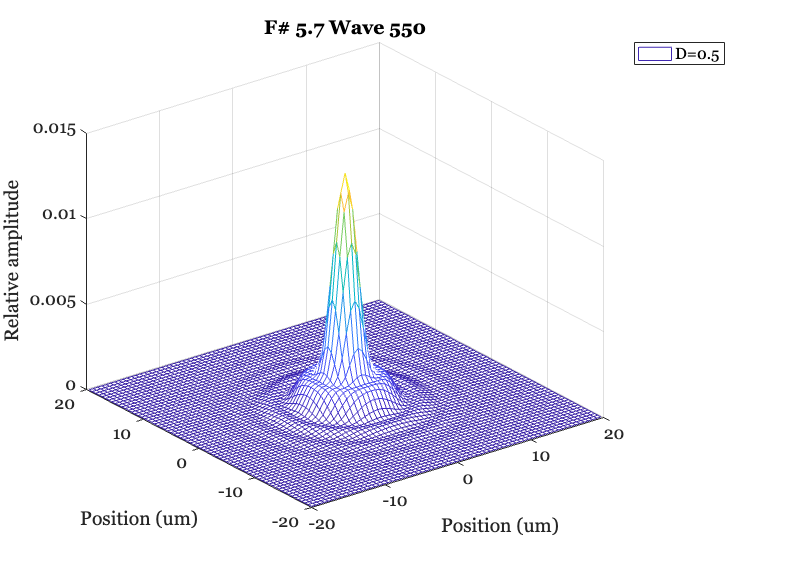

% Defocus of 0.5 diopters
thisD = 0.5;
wvf1 = wvfSet(wvf0,'zcoeffs',thisD,{'defocus'});
wvf1 = wvfCompute(wvf1);
wvfPlot(wvf1, 'psf', 'unit','um', 'plot range', 20);
legend({sprintf('D=%1.1f',thisD)})

## The impact of defocus on the amplitude of the OTF (MTF): cycles/mm

We use the same defocus parameters, starting from d=0 (diffraction limited) and then increasing.

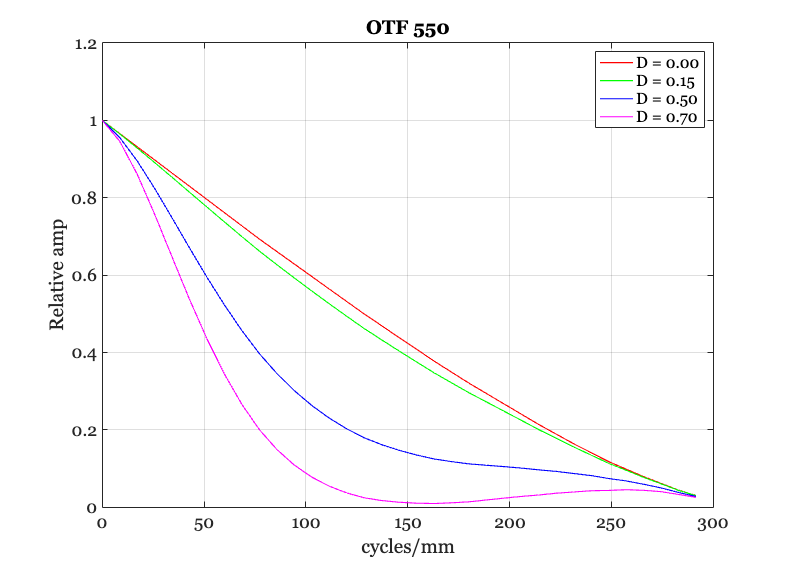

ieNewGraphWin;
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfCompute(wvf1);
    wvfPlot(wvf1, '1d otf', 'plot range', 300, 'window', false);
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
end

hold off
xlabel('cycles/mm'); ylabel('Relative amp'); grid on
legend(thisL);

## The amplitude of the OTF: cycles per degree

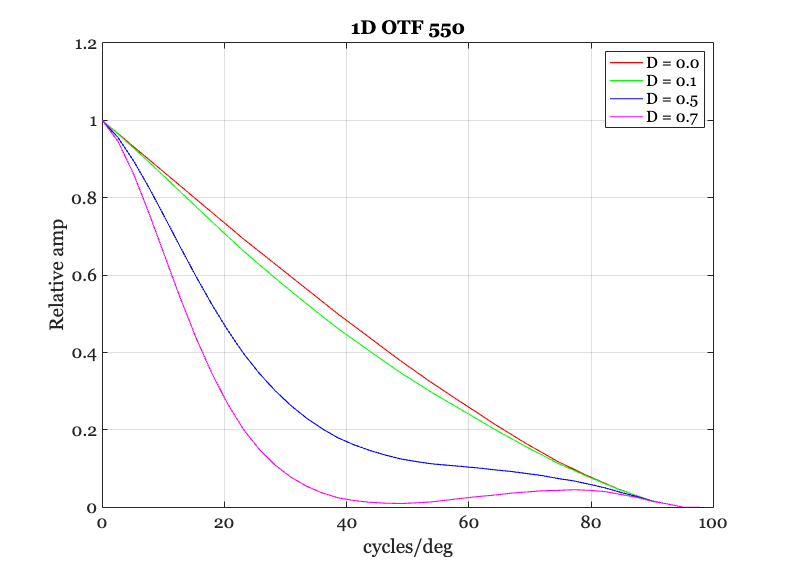

ieNewGraphWin;
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfCompute(wvf1);
    wvfPlot(wvf1, '1d otf angle', 'unit','deg', 'plot range', 100, 'window', false);
    hold on;
    thisL{ii} = sprintf('D = %0.1f',d(ii));
end

hold off
xlabel('cycles/deg'); ylabel('Relative amp'); grid on
legend(thisL)